# MSessionExplorer.AlignTime

Ignore code in this section

if exist('isRun', 'var') && isRun
    se = seRaw.Duplicate;
    se.isVerbose = false;
    se.SetColumn('hsv', 'is_tongue_out', @(x) x*0.6, 'each')
else
    edit MSessionExplorer.Examples.AlignTime
    return;
end

**Description**

help MSessionExplorer.AlignTime

  Align epochs by changing the origin of time in each epoch to the specified event times
  
    AlignTime(et)
    AlignTime(et, sourceTbName)
 
  Inputs
    et              An event name in an eventTimes table or a numeric vector of times to align 
                    to. Each time in the vector is relative wrt each row (epoch), which becomes 
                    the new zero time after alignment. 
    sourceTbName    If et is a string, then you must specify the name of an eventTimes table 
                    where this event name should be found. This avoids ambiguity of the same 
                    variable name found in multiple tables. The default is empty. 



**Example 1**

**Align data to new event times**

First, let's see some original data. The plotted are 5 epochs. Dots are 'lickOn' events in 'behavTime' table. Lines are 'is_tongue_out' time series in 'hsv' table. Currently, all epoch time is aligned to cue onset (shown in the 'cue' column of 'behavTime' table). 

se.Peek('behavTime', 'hsv')

    cue      posIndex      water    opto       lickOn           lickOff   
    ___    ____________    _____    ____    _____________    _____________

     0     [6×1 double]    1.832    NaN     [20×1 double]    [20×1 double]
     0     [6×1 double]    1.788    NaN     [19×1 double]    [19×1 double]
     0     [6×1 double]     1.87    NaN     [21×1 double]    [21×1 double]
     0     [6×1 double]    1.755    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.891    NaN     [16×1 double]    [16×1 double]
     0     [6×1 double]    1.742    NaN     [14×1 double]    [14×1 double]

         time           is_tongue_out     prob_tongue_out    tongue_bottom_lm
    _______________    

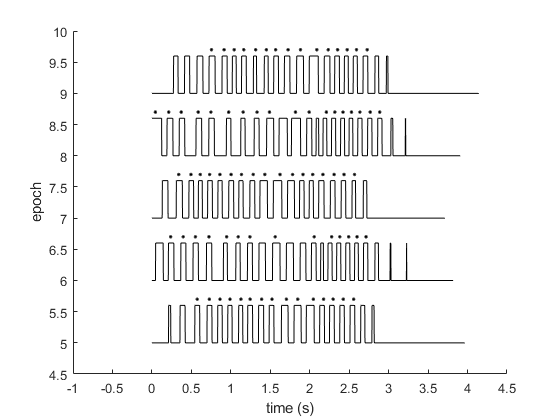

Visualize(se);

Reference times indicate the session/absolute times of the zero relative time in each epoch. 

se.GetReferenceTime('behavTime')'

ans = 	1.0e+03 *

    0.0504    0.0638    0.0754    0.0898    0.0985    0.1081    0.1176    0.1270    0.1342    0.1459    0.1529    0.1621    0.1697    0.1855    0.1932    0.2058    0.2128    0.2197    0.2329    0.2442    0.2515    0.2651    0.2725    0.2972    0.3041    0.3138    0.3249    0.3350    0.3435    0.3553    0.3633    0.3704    0.3775    0.3903    0.4030    0.4101    0.4182    0.4314    0.4395    0.4524    0.4599    0.4668    0.4738    0.4880    0.4954    0.5071    0.5150    0.5258    0.5328    0.5619


Now, we can align all epochs to, let's say, 0.5s. This single line of code sets 0.5s as the new zero epoch time for all epochs in all eventTimes and timeSeries tables.

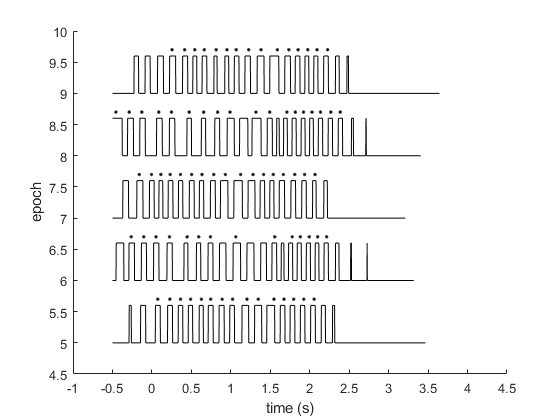

se.AlignTime(0.5);

Visualize(se)

Since we redefined zero epoch times, reference times changed accordingly, by +0.5s. Therefore, the absolute/session time of a given event never changes. 

se.GetReferenceTime('behavTime')'

ans = 	1.0e+03 *

    0.0509    0.0643    0.0759    0.0903    0.0990    0.1086    0.1181    0.1275    0.1347    0.1464    0.1534    0.1626    0.1702    0.1860    0.1937    0.2063    0.2133    0.2202    0.2334    0.2447    0.2520    0.2656    0.2730    0.2977    0.3046    0.3143    0.3254    0.3355    0.3440    0.3558    0.3638    0.3709    0.3780    0.3908    0.4035    0.4106    0.4187    0.4319    0.4400    0.4529    0.4604    0.4673    0.4743    0.4885    0.4959    0.5076    0.5155    0.5263    0.5333    0.5624


We can do something more meaningful. Let's align epoch times to the first lickOn (dot) in each epoch. First, we need to find these event times. 

bt = se.GetTable('behavTime');
firstLickOn = NaN(se.numEpochs, 1);
for k = 1 : se.numEpochs
    firstLickOn(k) = bt.lickOn{k}(1);
end
firstLickOn'

ans =    -0.1020   -0.2250    0.0860   -0.2800    0.0740   -0.2620   -0.1600   -0.4560    0.2550   -0.3130   -0.1400   -0.2590    0.2430   -0.2640   -0.1090   -0.2760   -0.0120   -0.3360    0.0590   -0.4380    0.0330   -0.2760    5.2410   -0.2450   -0.1860   -0.3080    0.1580   -0.3120   -0.1460   -0.3330    0.0100   -0.4120   -0.0720   -0.2500   -0.1020   -0.2930   -0.1870   -0.2390   -0.0640   -0.2990   -0.0070   -0.2840   -0.1110   -0.2560    0.2850   -0.2830   -0.1240   -0.2550   -0.0670   -0.2730


This line of code aligns each epoch across all eventTimes and timeSeries tables to a firstLickOn time, respectively. 

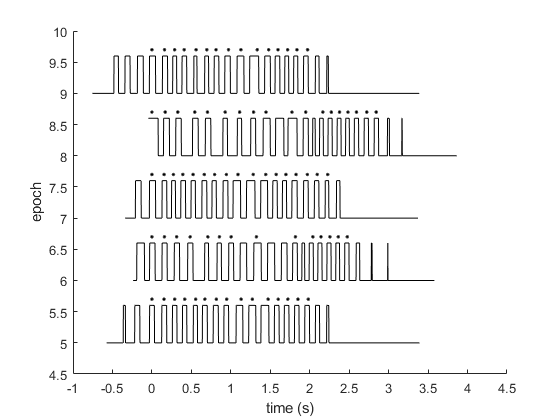

se.AlignTime(firstLickOn);

Visualize(se);

Reference times changed accordingly. 

se.GetReferenceTime('behavTime')'

ans = 	1.0e+03 *

    0.0508    0.0640    0.0760    0.0901    0.0991    0.1083    0.1180    0.1271    0.1350    0.1461    0.1532    0.1624    0.1704    0.1858    0.1936    0.2060    0.2133    0.2199    0.2334    0.2442    0.2520    0.2653    0.2782    0.2974    0.3045    0.3140    0.3255    0.3351    0.3438    0.3554    0.3638    0.3705    0.3779    0.3906    0.4034    0.4103    0.4185    0.4317    0.4400    0.4526    0.4604    0.4670    0.4742    0.4883    0.4962    0.5073    0.5154    0.5261    0.5333    0.5621


Finally, we can align time back to cue (or anything else). This time, however, we use column name and the source table name. 

AlignTime method gurantees the internal consistency and integrity. Any operation can be reversible. 

se.AlignTime('cue', 'behavTime')

Visualize(se);

**Helper function**

function Visualize(se)
[bt, hsv] = se.GetTable('behavTime', 'hsv');
figure; clf
MPlot.PlotRaster(bt.lickOn(5:9), (5:9)+.7, 'Color', 'k');
MPlot.PlotTraceLadder(hsv.time(5:9), hsv.is_tongue_out(5:9), 5:9, 'Color', 'k');
xlim([-1 4.5]); ylim([4.5 10]); xlabel('time (s)'); ylabel('epoch'); box off
end